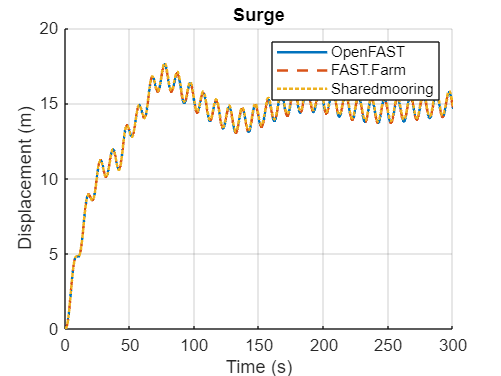

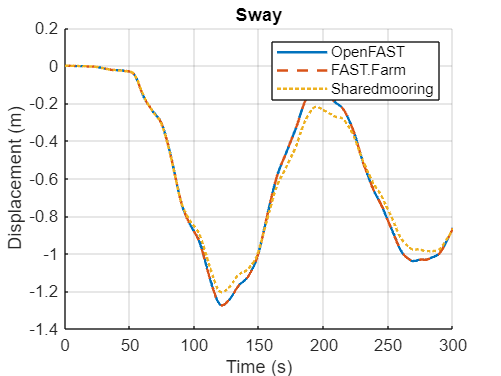

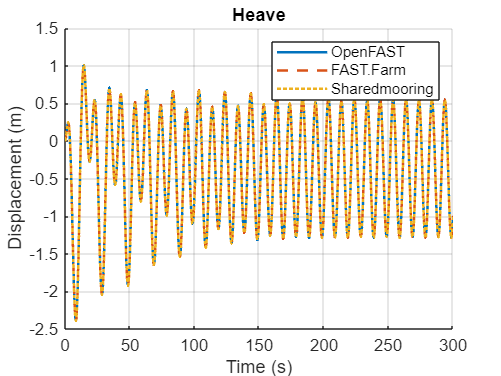

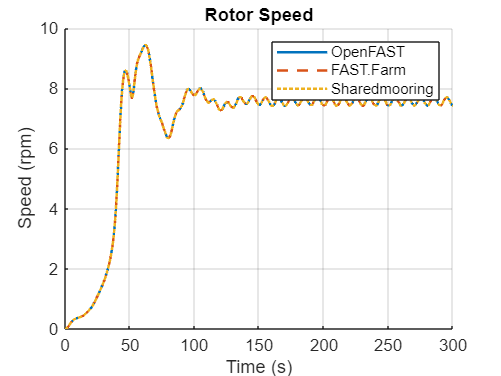

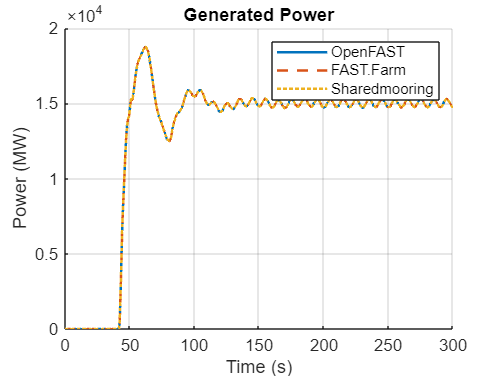

cd('C:\Users\User\Downloads\') 

files = {'OpenFAST.txt', 'FAST.Farm.txt', 'Sharedmooring.txt'};
data = cell(1, numel(files));

for i = 1:numel(files)
    data{i} = readmatrix(files{i});
end

[time1, surge1, sway1, heave1, RtSpeed1, GenPwr1] = deal(data{1}(:,1), data{1}(:,2), data{1}(:,3), data{1}(:,4), data{1}(:,19), data{1}(:,24));
[time2, surge2, sway2, heave2, RtSpeed2, GenPwr2] = deal(data{2}(:,1), data{2}(:,2), data{2}(:,3), data{2}(:,4), data{2}(:,19), data{2}(:,24));
[time3, surge3, sway3, heave3, RtSpeed3, GenPwr3] = deal(data{3}(:,1), data{3}(:,2), data{3}(:,3), data{3}(:,4), data{3}(:,19), data{3}(:,24));

variables = {'Surge', 'Sway', 'Heave', 'Rotor Speed', 'Generated Power'};
y_labels = {'Surge (m)', 'Sway (m)', 'Heave (m)', 'Rotor Speed (rpm)', 'Generated Power (MW)'};

data_sets = {surge1, surge2, surge3; 
             sway1, sway2, sway3; 
             heave1, heave2, heave3;
             RtSpeed1, RtSpeed2, RtSpeed3;
             GenPwr1, GenPwr2, GenPwr3};

line_styles = {'-', '--', ':'}; 

for i = 1:length(variables)
    figure; 
    hold on; 

    plot(time1, data_sets{i,1}, line_styles{1}, 'LineWidth', 1.5);
    plot(time2, data_sets{i,2}, line_styles{2}, 'LineWidth', 1.5);
    plot(time3, data_sets{i,3}, line_styles{3}, 'LineWidth', 1.5);
    
    grid on;
    title(variables{i});
    xlabel('Time (s)');
    ylabel(y_labels{i});
    legend('OpenFAST', 'FAST.Farm', 'Sharedmooring');
    hold off; 
    drawnow; 
    pause(0.1); 
end